# **Image Transmission via OFDM System Utilizing the IEEE 802.11a WLAN Physical Layer Implementation **

clc;
clear all ; 
close all ;

**Project requirements**

% SNR range for BER comparison
snr_range = 0:2:20;
imagepath="";
code_rate=1/3;
const_len=7;
cp_length=16;
fc=5.2^10^9;
fs=20*10^6;
gain=4;
% Initialize BER arrays
ber_zf_16qam = zeros(1, length(snr_range));
ber_w_16qam = zeros(1, length(snr_range));
ber_zf_bpsk = zeros(1, length(snr_range));
ber_w_bpsk = zeros(1, length(snr_range));

**BPSK and 16QAM modulation**

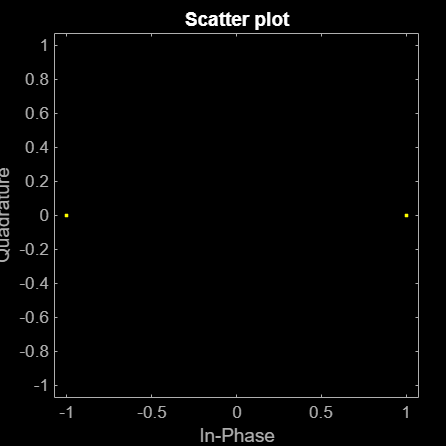

for i = 1:length(snr_range)
    snr = snr_range(i);
    
    % BPSK modulation
    modulation_type = "BPSK";
    [transmitted_signal,constellation,ofdm_symbol_with_cp,Whole_Data] = transmitter(imagepath, code_rate, const_len, modulation_type, cp_length, fc, fs, gain);
    received_signal = simulate_wireless_channel_AWGN(transmitted_signal, snr);
    received_signal = received_signal(1:length(transmitted_signal));
    amplified_signalrcv = LNA(received_signal, 1.01);
    demodsignal = IQ_Demodulation(amplified_signalrcv, fc, fs);
    parallel_data = Serial_To_Parallel(demodsignal);
    WithoutCP = Remove_Cyclic_Prefix(parallel_data, cp_length);
    fftt = FFT_operation(WithoutCP);
    freq_e_ZF = Frequency_Equalizer(fftt, 'ZF', 0,Whole_Data);
    freq_e_W = Frequency_Equalizer(fftt, 'W', snr,Whole_Data);
    % demapped_bits_zf = Symbol_Demapping(freq_e_ZF, modulation_type);
    % demapped_bits_w = Symbol_Demapping(freq_e_W, modulation_type);
    % decoded_bits_zf = FEC_Decoding(demapped_bits_zf, code_rate);
    % decoded_bits_w = FEC_Decoding(demapped_bits_w, code_rate);
    % ber_zf_bpsk(i) = sum(decoded_bits_zf ~= binary_data) / length(binary_data);
    % ber_w_bpsk(i) = sum(decoded_bits_w ~= binary_data) / length(binary_data);
    % 
end

for i = 1:length(snr_range)
    snr = snr_range(i);    
% 16QAM modulation
    modulation_type = "16QAM";
    [transmitted_signal,constellation,ofdm_symbol_with_cp,Whole_Data] = transmitter(imagepath, code_rate, const_len, modulation_type, cp_length, fc, fs, gain);
    received_signal = simulate_wireless_channel_AWGN(transmitted_signal, snr);
    received_signal = received_signal(1:length(transmitted_signal));
    amplified_signalrcv = LNA(received_signal, 1.01);
    demodsignal = IQ_Demodulation(amplified_signalrcv, fc, fs);
    parallel_data = Serial_To_Parallel(demodsignal);
    WithoutCP = Remove_Cyclic_Prefix(parallel_data, cp_length);
    fftt = FFT_operation(WithoutCP);
    freq_e_ZF = Frequency_Equalizer(fftt, 'ZF', 0,Whole_Data);
    freq_e_W = Frequency_Equalizer(fftt, 'W', snr,Whole_Data);
    % demapped_bits_zf = Symbol_Demapping(freq_e_ZF, modulation_type);
    % demapped_bits_w = Symbol_Demapping(freq_e_W, modulation_type);
    % decoded_bits_zf = FEC_Decoding(demapped_bits_zf, code_rate);
    % decoded_bits_w = FEC_Decoding(demapped_bits_w, code_rate);
    % ber_zf_16qam(i) = sum(decoded_bits_zf ~= binary_data) / length(binary_data);
    % ber_w_16qam(i) = sum(decoded_bits_w ~= binary_data) / length(binary_data);
end

**Constellation diagrams for 16QAM**

% Constellation diagrams for 16QAM
modulation_type = "16QAM";
transmitted_signal = transmitter(imagepath, code_rate, const_len, modulation_type, cp_length, fc, fs, gain);

Error using imread>get_full_filename (line 579)
Unable to find file "C:\Users\dell\Desktop\Adv_wireless\My_project\lunaluna.png".

Error in imread (line 372)
        fullname = get_full_filename(filename);

Error in <a href="matlab:matlab.lang.internal.introspective.errorDocCallback('Adv_wireless_finalProject>imageToBinary', 'D:\Downloads\Adv_wireless_finalProject.mlx', 225)" style="font

received_signal = simulate_wireless_channel_AWGN(transmitted_signal, 10); % Choose any desired SNR
received_signal = received_signal(1:length(transmitted_signal));
amplified_signalrcv = LNA(received_signal, 1.01);
demodsignal = IQ_Demodulation(amplified_signalrcv, fc, fs);
parallel_data = Serial_To_Parallel(demodsignal);
WithoutCP = Remove_Cyclic_Prefix(parallel_data, cp_length);
fftt = FFT_operation(WithoutCP);
freq_e_ZF = Frequency_Equalizer(fftt, 'ZF', 0);
freq_e_W = Frequency_Equalizer(fftt, 'W', 10);

figure;
scatter(real(freq_e_ZF), imag(freq_e_ZF), 'b.');
title('Constellation Diagram - ZF Equalizer (16QAM)');
xlabel('Real');
ylabel('Imaginary');

figure;
scatter(real(freq_e_W), imag(freq_e_W), 'r.');
title('Constellation Diagram - Wiener Equalizer (16QAM)');
xlabel('Real');
ylabel('Imaginary');

**Comparison between the BER performance of the ZF equalizer, and the Weiner equalizer for BPSK modulation, and 1/3 code rate**

% Plot BER comparison for BPSK
figure;
semilogy(snr_range, ber_zf_bpsk, 'b-o', 'LineWidth', 1.5);
hold on;
semilogy(snr_range, ber_w_bpsk, 'r-*', 'LineWidth', 1.5);
xlabel('SNR (dB)');
ylabel('BER');
title('BER Comparison for BPSK');
legend('ZF Equalizer', 'Wiener Equalizer');
grid on;

**Comparison between the BER performance of the ZF equalizer, and the Weiner equalizer for 16QAM modulation, and 1/3 code rate using the floating-point implementation**

% % Plot BER comparison for 16QAM
% figure;
% semilogy(snr_range, ber_zf_16qam, 'b-o', 'LineWidth', 1.5);
% hold on;
% semilogy(snr_range, ber_w_16qam, 'r-*', 'LineWidth', 1.5);
% xlabel('SNR (dB)');
% ylabel('BER');
% title('BER Comparison for 16QAM');
% legend('ZF Equalizer', 'Wiener Equalizer');
% grid on;

**Testing the Project**

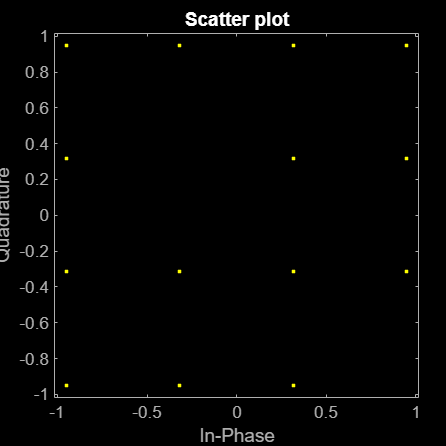


% this part of the code is for testing the project only
% consider ignoring or deleting this part at the end

imagepath="C:\Users\dell\Desktop\Adv_wireless\My_project\lunaluna.png";
code_rate=1/3; % or 2/3 or 3/4
const_len=7;
modulation_type="16QAM"; %BPSK or 16QAM OR 64QAM
M=4;
cp_length=16;
fc=5.2^10^9;
fs=20*10^6;
gain=4; %6db
[transmitted_signal,trans_constellation,B4IQ,symParallel] = transmitter(imagepath,code_rate,const_len,modulation_type,cp_length,fc,fs,gain);

received_signal = simulate_wireless_channel(transmitted_signal);
received_signal = received_signal(1:length(transmitted_signal));
max(abs(received_signal)) %less than 40

ans = 1.2945


amplified_signalrcv = LNA(received_signal, 1.01)

amplified_signalrcv =   -0.0983 - 0.0246i  -0.1363 - 0.0341i  -0.1760 - 0.0624i  -0.1836 - 0.0715i   0.3002 + 0.0467i   0.3998 + 0.0719i   0.9235 + 0.2943i   0.5247 + 0.2132i   0.3879 + 0.2543i   0.4601 + 0.1929i   0.2658 + 0.0999i  -0.0013 + 0.0665i   0.1206 + 0.0716i   0.1661 + 0.0246i   0.6058 + 0.1637i  -0.2673 - 0.0314i  -0.3214 + 0.0302i  -0.3316 - 0.1418i  -0.5987 - 0.2376i  -0.3973 - 0.1467i  -0.1826 - 0.1359i   0.1324 - 0.0295i  -0.1366 - 0.0458i  -0.0752 + 0.0217i  -0.3626 - 0.1133i  -0.3910 - 0.1220i  -0.1681 - 0.1043i   0.0998 - 0.0423i  -0.6817 - 0.1864i  -0.3100 - 0.0420i  -0.3322 - 0.2069i  -0.2168 - 0.1212i  -0.0699 - 0.0488i   0.1848 + 0.0223i  -0.0615 - 0.0207i  -0.1093 + 0.0133i   0.0100 - 0.0077i  -0.0606 - 0.0458i  -0.2473 - 0.0574i  -0.1282 - 0.0358i   0.1871 - 0.0007i   0.3785 + 0.0715i  -0.2855 - 0.0244i   0.1547 + 0.1154i  -0.1193 - 0.0951i   0.3863 + 0.1064i   0.0823 + 0.0145i   0.3608 + 0.1602i  -0.3893 - 0.0804i  -0.1586 + 0.0105i


max(abs(amplified_signalrcv)) %less than 40

ans = 1.3075

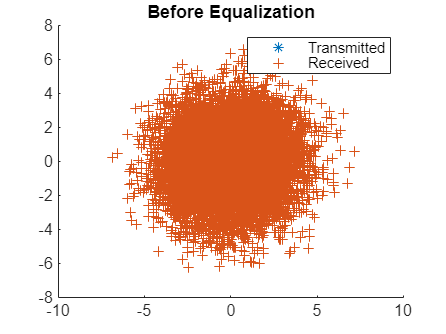


demodsignal= amplified_signalrcv;%IQ_Demodulation(received_signal, fc, fs);

parallel_data=Serial_To_Parallel(demodsignal);
WithoutCP=Remove_Cyclic_Prefix(parallel_data,16);

fftt=FFT_operation(WithoutCP);

freq_e_ZF= Frequency_Equalizer(fftt,'ZF',0,symParallel);     % zero or any value, will not be used
freq_e_W= Frequency_Equalizer(fftt,'W',10,symParallel);

szfft=size(fftt);
rfft=reshape(fftt,[1,szfft(1)*szfft(2)]);
figure;
scatter(real(trans_constellation),imag(trans_constellation),'*');
hold on;
scatter(real(rfft'), imag(rfft'),'+');
legend('Transmitted','Received');
title('Before Equalization');

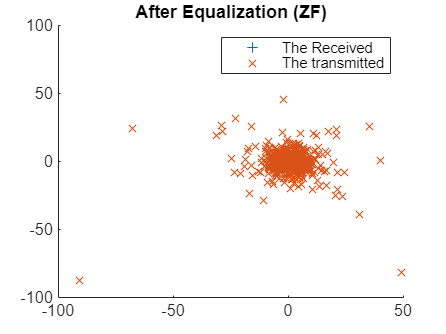


szfreq_e_ZF=size(freq_e_ZF);
rfreq_e_ZF=reshape(freq_e_ZF,[1,szfreq_e_ZF(1)*szfreq_e_ZF(2)]);
figure;
scatter(real(trans_constellation),imag(trans_constellation),'+');
hold on;
scatter(real(rfreq_e_ZF),imag(rfreq_e_ZF),'x');
legend('The Received','The transmitted');
title('After Equalization (ZF)');

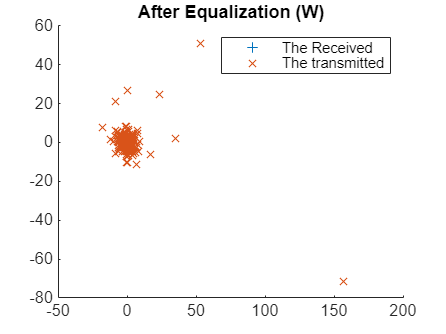


szfreq_e_W=size(freq_e_W);
rfreq_e_W=reshape(freq_e_W,[1,szfreq_e_W(1)*szfreq_e_W(2)]);
figure;
scatter(real(trans_constellation),imag(trans_constellation),'+');
hold on;
scatter(real(rfreq_e_W),imag(rfreq_e_W),'x');
legend('The Received','The transmitted');
title('After Equalization (W)');

figure;
scatter(real(transmitted_signal),imag(transmitted_signal),'*');


**Testing Each Block**

- **Image**

imagepath="C:\Users\dell\Desktop\Adv_wireless\My_project\lunaluna.png";
binary_data=imageToBinary(imagepath);

- **FER**

encoded_data_13 = FEC_Encoding(binary_data, 1/3 , 7);
encoded_data_23 = FEC_Encoding(binary_data, 2/3 , 7);
encoded_data_34 = FEC_Encoding(binary_data, 3/4 , 7);

- **Sympol Mapping**

constellation_test = Symbol_Mapping(encoded_data_23, "BPSK");

- **Serial to Parallel**

SymParallel = Parallel_To_Serial(constellation_test);

- **Nulls**

Whole_Data = AddNullsandPilots(SymParallel);

- **IDFT**

IFFT = Perform_IFFT(Whole_Data);

- **Cyclic prefix**

ofdm_symbol_with_cp = Add_Cyclic_Prefix(IFFT, 16);

- **I/Q Modulation**

modulated_signal = IQ_Modulation(ofdm_symbol_with_cp, 5.2*10^9 , 20*10^6);

- **Amplifing**

amplified_signal=Power_Amplification(modulated_signal,4);
max(abs(amplified_signal)) %less than 40


- **Transmitting**

imagepath="C:\Users\dell\Desktop\Adv_wireless\My_project\lunaluna.png";
code_rate=1/3; % or 2/3 or 3/4
const_len=7;
modulation_type="16QAM"; %BPSK or 16QAM OR 64QAM
cp_length=16;
fc=5.2^10^9;
fs=20*10^6;
gain=4; %6db
transmitted_signal = transmitter(imagepath,code_rate,const_len,modulation_type,cp_length,fc,fs,gain);

%specAn= spectrumAnalyzer('SampleRate', fs, 'Title', 'Magnitude Spectrum of the Baseband Signal');
%spectrumAnalyzer(transpose(specAn));
spec = fftt(transmitted_signal);

n = length(transmitted_signal);          % number of samples
f = (0:n-1)*(fs/n);     % frequency range
power = abs(spec).^2/n;    % power of the DFT

plot(f,power)
xlabel('Frequency')
ylabel('Power')

- **Wireless channel without AWGN**

received_signal = simulate_wireless_channel(transmitted_signal);
received_signal = received_signal(1:length(transmitted_signal));
max(abs(received_signal)) %less than 40

- **Wireless channel with AWGN**

SNR_dB = 10;
received_signal_ = simulate_wireless_channel_AWGN(transmitted_signal,SNR_dB);
received_signal = received_signal(1:length(transmitted_signal));
max(abs(received_signal))


- **Low noise amplifing**

amplified_signalrcv = LNA(received_signal, 1.01)
max(abs(amplified_signalrcv)) %less than 40

- **I/Q Demodulation**

demodsignal=IQ_Demodulation(received_signal, fc, fs);

- **Serial to parallel**

parallel_data=Serial_To_Parallel(demodsignal);

- **Removing CP**

WithoutCP=Remove_Cyclic_Prefix(parallel_data,16);

- **FFT**

fftt=FFT_operation(WithoutCP);

- **Wiener Equalizing **

freq_e_W = Frequency_Equalizer(fftt, 'W', snr,Whole_Data);

- **ZF equalization**

freq_e_ZF = Frequency_Equalizer(fftt, 'ZF', 0,Whole_Data);

- **Demapping**

demapped_bits_zf = Symbol_Demapping(freq_e_ZF, modulation_type);
demapped_bits_w = Symbol_Demapping(freq_e_W, modulation_type);

- **FEC Decoding**

decoded_bits_zf = FEC_Decoding(demapped_bits_zf, code_rate);
decoded_bits_w = FEC_Decoding(demapped_bits_w, code_rate);

**Functions**

- **Importing Image**

**The imageToBinary function converts an image to a binary vector. It reads an image, converts it to grayscale, normalizes the pixel values, and transforms them into an 8-bit binary representation. The binary values are then reshaped into a single row vector.**

**Inputs: imagepath: A string specifying the file path of the image. **

**Outputs: binary_data: A 1-dimensional array containing the binary representation of the image's pixel values.**

function binary_data = imageToBinary(imagepath)
    % img to binary
    image = rgb2gray(imread(imagepath));
    image_normalized = double(image) / 255;
    binary_data = reshape(dec2bin(image_normalized * 255, 8)', 1, []) - '0';
end

- **Forward error correction is applied using convolutional coding with rates 1/3, 2/3, or 3/4 :**

**Description: The FEC_Encoding function performs convolutional encoding on input data using specified coding rates and constraint lengths. It selects the appropriate trellis structure based on the given code rate and encodes the data using this trellis. The encoded data is then output as a binary sequence. **

**Inputs: data: A binary vector representing the input data to be encoded. code_rate: The coding rate (e.g., 1/3, 2/3, 3/4) determining the redundancy level. const_len: The constraint length for the convolutional encoder. **

**Outputs: encoded_data: A binary vector containing the encoded data**

function encoded_data = FEC_Encoding(data, code_rate, const_len)
    % conv encod
    switch code_rate
        case 1/3
            trellis = poly2trellis(const_len, [171 133 133]);
        case 2/3
            trellis = poly2trellis(const_len, [171 133 133]);
        case 3/4
            trellis = poly2trellis(const_len, [171 133 133 133]);
        otherwise
            error('wrong code rate');
    end
    encoded_data = convenc(data, trellis);
end

- **In Symbol Mapping The OFDM subcarriers are modulated using BPSK, QPSK, 16QAM, or 64 QAM depending on the desired rate. The bitstream is divided into groups of size 1, 2, 4 or 6; respectively, and mapped to complex numbers representing the constellation points : **

**The Symbol_Mapping function maps input binary data to modulation symbols based on the specified modulation type. It determines the constellation size and normalization factor, groups the data bits accordingly, and maps these groups to symbols using Gray coding. The output is a complex-valued constellation vector. **

**Inputs: data_bits: A binary vector representing the input data bits. modulation_type: A string specifying the modulation type (e.g., 'BPSK', 'QPSK', '16QAM', '64QAM'). **

**Outputs: constellation: A vector of complex values representing the modulated symbols.**

function constellation = Symbol_Mapping(data_bits, modulation_type)
    % Determine constellation size based on modulation type
    if strcmp(modulation_type, 'BPSK')
        group_size = 1;
        constellation_size=2;
        normalization_factor = 1;
    elseif strcmp(modulation_type, 'QPSK')
        group_size = 2;
        constellation_size=4;
        normalization_factor = 1/sqrt(2);
    elseif strcmp(modulation_type, '16QAM')
        group_size = 4;
        constellation_size=16;
        normalization_factor = 1/sqrt(10);
    elseif strcmp(modulation_type, '64QAM')
        group_size = 6;
        constellation_size=64;
        normalization_factor = 1/sqrt(42);
    else
        error('wrong modulation type');
    end
    % Group data bits based on constellation size
    data_grouped = [];
    group=[];
    for i=1:length(data_bits)
        bit=data_bits(i);
        group=[group bit];
        if mod(i,group_size)==0
            data_grouped=[data_grouped ; group];
            group=[];
        end
    end
    %num_subcarriers=64;
    % Symbol mapping with Gray encoding
    constellation_decimal = bi2de(data_grouped, 'left-msb');
    constellation = qammod(constellation_decimal, constellation_size, 'gray') * normalization_factor;
    figure;
    scatterplot(constellation);
end

- **Serial to Parallel**

**Description: The Parallel_To_Serial function converts parallel data into serial form. It reshapes the input data into a matrix with 48 rows, effectively organizing the data into serial format. **

**Inputs: data: A vector representing the parallel data to be converted. **

**Outputs: SymParallel: A matrix with 48 rows, where each column represents a segment of the serial data.**

function SymParallel = Parallel_To_Serial(data)
    % Convert parallel data to serial
    SymParallel = reshape(data, [48, length(data)/48]);
end

- **Adding Nulls and Pilots**

**Description: The AddNullsandPilots function inserts null subcarriers and pilot symbols into the input parallel data. It organizes the data by adding null subcarriers and pilot symbols at specified positions within the data matrix. **

**Inputs: SymParallel: A matrix representing the parallel data to which nulls and pilots will be added. **

**Outputs: Whole_Data: A matrix with null subcarriers and pilot symbols inserted, structured for further processing.**

function Whole_Data = AddNullsandPilots(SymParallel)
    PilotsI = [8,22,44,58];
    sz=size(SymParallel);
    nullsubcar = zeros(1,sz(2));
    Whole_Data = [nullsubcar; SymParallel(1:6,:);nullsubcar;....
        SymParallel(7:19,:);nullsubcar;SymParallel(20:24,:);...
        repmat(nullsubcar,11,1);SymParallel(25:29,:);nullsubcar;...
        SymParallel(30:42,:);nullsubcar;SymParallel(43:48,:)];
    pilots = [1,1,1,-1];

    for i = 1:2:length(SymParallel)
        Whole_Data(PilotsI,i)=pilots;
    end

    
end

- **IDFT**

**Description: The Perform_IFFT function applies the Inverse Fast Fourier Transform (IFFT) to the input data matrix. It transforms the frequency-domain data into the time domain using a 64-point IFFT. **

**Inputs: Whole_Data: A matrix containing the data to be transformed from the frequency domain to the time domain. **

**Outputs: IFFT: A matrix containing the time-domain representation of the input data after applying the 64-point IFFT.**

function IFFT = Perform_IFFT(Whole_Data)   % Perform IFFT
    IFFT = ifft(Whole_Data,64);
end

- **Add Cyclic prefix to the data stream**

**Description: The Add_Cyclic_Prefix function adds a cyclic prefix to each OFDM symbol and then converts the data from parallel to serial form. It appends the last part of each symbol to its beginning to create the cyclic prefix, and then flattens the matrix into a single vector. **

**Inputs: ofdm_symbol: A matrix representing the OFDM symbols. cp_length: An integer specifying the length of the cyclic prefix. **

**Outputs: result: A vector containing the OFDM symbols with cyclic prefixes in serial form.**

function result = Add_Cyclic_Prefix(ofdm_symbol, cp_length)
    % Add cyclic prefix
    ofdm_symbol_with_cp = [ofdm_symbol(end-cp_length+1:end,:);ofdm_symbol];
    %parallel to serial
    result=[];
    sz=size(ofdm_symbol_with_cp);
    for i=1:sz(1)
        result=[result, ofdm_symbol_with_cp(i,:)];
    end
end

- **I/Q Modulation**

**Description: The IQ_Modulation function carries out In-phase Quadrature (IQ) modulation on the provided OFDM symbols with cyclic prefix. It modulates the real part of the OFDM symbols onto a cosine carrier and the imaginary part onto a sine carrier, then combines them to form the modulated signal. **

**Inputs: ofdm_symbol_with_cp: A vector containing the OFDM symbols with cyclic prefixes in serial form. fc: The carrier frequency for modulation. fs: The sampling frequency. **

**Outputs: modulated_signal: The resulting modulated signal after IQ modulation.**

function modulated_signal = IQ_Modulation(ofdm_symbol_with_cp, fc, fs)
    % Create time vector
    t = (0:1/fs:(1/fs)*(length(ofdm_symbol_with_cp)-1));%(0:length(ofdm_symbol_with_cp)-1) / fs;
    I = real(ofdm_symbol_with_cp) .* cos(2*pi*fc*t);
    Q = imag(ofdm_symbol_with_cp) .* sin(2*pi*fc*t);
    % Combine I/Q components
    modulated_signal = I + Q;
end

- **Amplifing**

**Description: The Power_Amplification function amplifies the input signal by multiplying it with a specified gain factor. **

**Inputs: signal: The input signal to be amplified. gain: The amplification factor by which the signal is multiplied. **

**Outputs: amplified_signal: The resulting signal after amplification.**

function amplified_signal = Power_Amplification(signal, gain)
    amplified_signal = signal * gain;
end


- **Implementaion of the transmitter**

**Description: The simulate_wireless_channel function simulates a wireless channel by convolving the transmitted signal with a FIR filter. Optionally, it can add Additive White Gaussian Noise (AWGN) to the received signal based on the specified Signal-to-Noise Ratio (SNR) in decibels (dB). **

**Inputs: transmitted_signal: The signal transmitted through the wireless channel. SNR_dB (optional): The Signal-to-Noise Ratio (SNR) in decibels (dB). If provided, AWGN is added to the received signal. **

**Outputs: received_signal: The received signal after passing through the wireless channel, possibly with AWGN added.**

function [transmitted_signal,constellation,ofdm_symbol_with_cp,Whole_Data] = transmitter(imagepath,code_rate,const_len,modulation_type,cp_length,fc,fs,gain)
    binary_data = imageToBinary(imagepath);
    encoded_data = FEC_Encoding(binary_data, code_rate, const_len);
    constellation = Symbol_Mapping(encoded_data, modulation_type);% Symbol mapping
    SymParallel = Parallel_To_Serial(constellation);
    Whole_Data = AddNullsandPilots(SymParallel);
    IFFT = Perform_IFFT(Whole_Data);
    ofdm_symbol_with_cp = Add_Cyclic_Prefix(IFFT, cp_length);
    modulated_signal = IQ_Modulation(ofdm_symbol_with_cp, fc, fs);
    transmitted_signal = Power_Amplification(modulated_signal, gain);
end

### 2)Simultion of Wireless Channel

- **Wireless channel simulation (without AWGN)**

function received_signal = simulate_wireless_channel(transmitted_signal)
    % Define the FIR filter coefficients
    h = [0.8208+0.2052j; 0.4104+0.1026j; 0.2052+0.2052j; 0.1026+0.1026j];
    % Convolve transmitted signal with FIR filter
    received_signal = conv(transmitted_signal, h);
end

- **with AWGN**

function received_signal = simulate_wireless_channel_AWGN(transmitted_signal,SNR_dB)
    h = [0.8208+0.2052j; 0.4104+0.1026j; 0.2052+0.2052j; 0.1026+0.1026j];
    % Convolve transmitted signal with FIR filter
    received_signal = conv(transmitted_signal, h);
    
    % AWGN parameters
    SNR = 10^(SNR_dB/10);  % Convert SNR to linear scale
    % Generate complex Gaussian noise with the same length as the received signal
    noise = sqrt(0.5/SNR) * (randn(size(received_signal)) + 1i*randn(size(received_signal)));

    % Add noise to the received signal
    received_signal = received_signal + noise;
end


### 3)Receiver part Functionallities && employing 

- **Low noise amplifier**

**The LNA function simulates the Low-Noise Amplifier (LNA) stage in a communication receiver. It amplifies the received signal by multiplying it with a specified gain factor. **

**Inputs: received_signal: The received signal to be amplified. gain: The amplification factor applied by the Low-Noise Amplifier (LNA). **

**Outputs: amplified_signalrcv: The received signal after amplification by the LNA.**

function amplified_signalrcv = LNA(received_signal, gain)
    amplified_signalrcv = received_signal * gain;
end

- **I/Q Demodulation**

**The IQ_Demodulation function performs In-phase Quadrature (IQ) demodulation on the received signal. It extracts the In-phase (I) and Quadrature (Q) components by multiplying the received signal with cosine and sine carriers, respectively. Then, it combines these components to reconstruct the demodulated signal. **

**Inputs: received_signal: The received modulated signal to be demodulated. fc: The carrier frequency used for modulation. fs: The sampling frequency used for demodulation. **

**Outputs: Demodulated: The demodulated signal containing both the In-phase (I) and Quadrature (Q) components.**

function Demodulated = IQ_Demodulation(received_signal, fc, fs)
    % Create time vector
    t = (0:1/fs:(1/fs)*(length(received_signal)-1));%(0:length(received_signal)-1) / fs;
    % Demodulate in-phase (I) and quadrature (Q) components
    I = received_signal .* cos(2*pi*fc*t);
    Q = -received_signal .* sin(2*pi*fc*t);
    Demodulated=I+(1j*Q);
end

- **Serial to parallel**

**Description: The Serial_To_Parallel function converts serial data into parallel format. It reshapes the serial data into a matrix with 80 columns, effectively organizing the data into parallel streams. **

**Inputs: serial_data: A vector representing the serial data to be converted into parallel format. **

**Outputs: parallel_data: A matrix with 80 columns, where each row represents a segment of the parallel data.**

function parallel_data = Serial_To_Parallel(serial_data)
    % Convert serial data to parallel
    parallel_data = reshape(serial_data, [], 80)';
end

- **Removing CP**

**Description: The Remove_Cyclic_Prefix function removes the cyclic prefix from each OFDM symbol. It extracts the data part of each symbol by discarding the initial portion corresponding to the cyclic prefix length. **

**Inputs: ofdm_symbol_with_cp: A matrix representing OFDM symbols with cyclic prefixes. cp_length: An integer specifying the length of the cyclic prefix. **

**Outputs: WithoutCP: A matrix containing the OFDM symbols without the cyclic prefix.**

function WithoutCP = Remove_Cyclic_Prefix(ofdm_symbol_with_cp, cp_length)
    % Remove cyclic prefix
    WithoutCP = ofdm_symbol_with_cp(cp_length+1:end,:);
end

- **FFT**

**Description: The FFT_operation function performs Fast Fourier Transform (FFT) on the input parallel data. It transforms the data from the time domain to the frequency domain using a 64-point FFT. **

**Inputs: parallel_data: A matrix representing the parallel data to be transformed into the frequency domain. **

**Outputs: frequency_domain_data: A matrix containing the data transformed into the frequency domain using FFT.**

function frequency_domain_data = FFT_operation(parallel_data)
    % Perform FFT
    frequency_domain_data = fft(parallel_data, 64);
end

- **Channel Estimation**

**Description: The interpolate function performs channel estimation by interpolating the channel response at pilot subcarrier indices. It interpolates the channel frequency response using cubic interpolation along the subcarrier axis and then interpolates along the time axis. **

**Inputs: PilotsIndc: Indices of pilot subcarriers. gg: Channel frequency response matrix. r: Number of rows (frequency bins). c: Number of columns (time samples). **

**Outputs: interpTime: Interpolated channel response matrix in the time domain**

function interpTime = interpolate(PilotsIndc,gg,r,c)
interpFreq = zeros(r, c);
interpTime = zeros(r, c);
for o = 1 :2: c
f_real = fit(PilotsIndc',gg(:,ceil(o/2)),'cubicinterp');
interpFreq(:,o) = f_real(1:r);
end
for u = 1 : r
    f_imag = fit([1:2:c]',interpFreq(u,1:2:end)','cubicinterp');
    interpTime(u,:) = f_imag(1:c);
end
end

- **Frequency Equalizing **

**Description: Equalizes the frequency response of the received signal. **

**Inputs: fft: Matrix representing the received signal in the frequency domain. equalization_type: Type of equalization method ('ZF' or 'W'). SNR: Signal-to-Noise Ratio. **

**Output: equalized_data: Matrix representing the equalized signal in the frequency domain. **

function equalized_data = Frequency_Equalizer(fft,equalization_type,SNR,SymParallel)
    PilotsI = [8,22,44,58];
    G = fft(PilotsI,1:2:end) ./ SymParallel(PilotsI,1:2:end);  
    sz=size(fft);
    n = sz(1)*sz(2);
    interpolation_T_Real = interpolate(PilotsI, real(G), 64, n/64);
    interpolation_T_Imag = interpolate(PilotsI, imag(G), 64, n/64);
    estimatedChannel = interpolation_T_Real + 1i * interpolation_T_Imag;

    % zero-forcing
    ZF = fft./estimatedChannel;


    % Wiener
    % multiplies the received signal by a filter coefficient that depends on both the channel frequency response and the SNR
    estimatedChannel_conj = conj(estimatedChannel);
    w_1 = estimatedChannel_conj .*fft;
    w_2 = 1/SNR + (abs(estimatedChannel).^2 .* fft);
    W = w_1 ./ w_2;   

    if equalization_type == "ZF"
        equalized_data = ZF;
    elseif equalization_type == "W"
        equalized_data = W;
    else 
        error('Invalid equalization method')
    end


end

- **Demapping**

**Description: Demaps symbols back to binary data based on modulation type. **

**Inputs: constellation: Vector containing the modulated symbols. modulation_type: Type of modulation used ('BPSK', 'QPSK', '16QAM', '64QAM'). **

**Output: demapped_bits: Matrix containing the demapped binary data.**

function demapped_bits = Symbol_Demapping(constellation, modulation_type)
    % Determine constellation size based on modulation type
    if strcmp(modulation_type, 'BPSK')
        group_size = 1;
        constellation_size=2;
        normalization_factor = 1;
    elseif strcmp(modulation_type, 'QPSK')
        group_size = 2;
        constellation_size=4;
        normalization_factor = 1/sqrt(2);
    elseif strcmp(modulation_type, '16QAM')
        group_size = 4;
        constellation_size=16;
        normalization_factor = 1/sqrt(10);
    elseif strcmp(modulation_type, '64QAM')
        group_size = 6;
        constellation_size=64;
        normalization_factor = 1/sqrt(42);
    else
        error('Invalid modulation type');
    end
    demapped_symbols = qamdemod(constellation / normalization_factor, constellation_size, 'gray')* (1/normalization_factor);
    demapped_data_bits = de2bi(demapped_symbols, log2(constellation_size), 'left-msb');
end


- **Parallel to Serial**

**Description: Converts parallel data to serial format. **

**Input: parallel_data: Matrix containing parallel data. **

**Output: serial_data: Vector containing serial data.**

function serial_data = Parallel_to_Serial(parallel_data)
    % Convert parallel data to serial
    serial_data = parallel_data(:)
end

- **FEC Decoding**

**Description: Decodes forward error-correcting encoded data. **

**Inputs: received_data_bits: Binary data received after transmission. code_rate: Rate of the convolutional code used (1/3, 2/3, 3/4). **

**Output: decoded_data_bits: Decoded binary data.**

function decoded_data_bits = FEC_Decoding(received_data_bits, code_rate)
    % Define convolutional coding parameters based on code rate
    if code_rate == 1/3
        trellis = poly2trellis(const_len, [171 133 133]);
    elseif code_rate == 2/3
        trellis = poly2trellis(const_len, [171 133 133]);
    elseif code_rate == 3/4
        trellis = poly2trellis(const_len, [171 133 133 133]);
    else
        error('Invalid code rate');
    end
    % Convolutional decoding
    decoded_data_bits = vitdec(received_data_bits, trellis, 100, 'trunc', 'hard');
end

**Bonus**

% function [equalized_data, papr] = Frequency_Equalizer_B(fft, equalization_type, SNR)
%     % Clipping to reduce PAPR
%     fft_clipped = Clip(fft);
% 
%     % Filtering to reduce out-of-band emissions
%     fft_filtered = Filter(fft_clipped);
% 
%     % Calculate channel frequency response
%     sz = size(fft_filtered);
%     pilot = ones(1, sz(2));
%     pilots = [pilot; pilot; pilot; pilot*-1];
%     indices = [8, 22, 44, 58];
%     G = fft_filtered(indices, :) ./ pilots;
% 
%     % Interpolation in time domain
%     n = sz(1) * sz(2);
%     interpolation_T_Real = interpolate(indices, real(G), 64, n/64);
%     interpolation_T_Imag = interpolate(indices, imag(G), 64, n/64);
%     estimatedChannel = interpolation_T_Real + 1i * interpolation_T_Imag;
% 
%     % Equalization
%     ZF = fft_filtered ./ estimatedChannel;
%     snr = 18;  % Remove later
%     estimatedChannel_conj = conj(estimatedChannel);
%     w_1 = estimatedChannel_conj .* fft_filtered;
%     w_2 = 1/SNR + (abs(estimatedChannel).^2 .* fft_filtered);
%     W = w_1 ./ w_2;
% 
%     % Select equalization type
%     if equalization_type == "ZF"
%         equalized_data = ZF;
%     elseif equalization_type == "W"
%         equalized_data = W;
%     else
%         error('Invalid equalization method');
%     end
% 
%     % Calculate PAPR
%     papr = Calculate_PAPR(equalized_data);
% end
% 
% function clipped_signal = Clip(signal)
% 
%     clipped_signal = max(min(signal, 1), -1); % Clip between -1 and 1
% end
% 
% function filtered_signal = Filter(signal)
% 
%     filtered_signal = signal; % Placeholder, replace with actual implementation
% end
% 
% function papr = Calculate_PAPR(signal)
% 
%     papr = max(abs(signal).^2) / mean(abs(signal).^2); % Calculate PAPR
% end
% 
% % Other functions (Demapping, FEC Decoding, etc.) remain unchanged.